## Understanding hyperparameters

This tutorial is about getting to know the hyperparameters of EXTRACT. For the purpose of this tutorial, download the movie, whose link is given below. This is among those movies that we used for the  Fig. 4 of our paper that introduces EXTRACT. Use the script  'tutorial_fig4.m' as a starting point to tune hyperparameters for most  satisfactory cell extraction process. Read below for the meaning behind  each relevant hyperparameter and the simple ways to optimize them  without diving too deep.

Before getting started, grab the movie and place in the `sample_data` folder. It should be named `Fig4_example.h5`. This file is 2.2 GB in size and is too large for Matlab Online.

The movie: [https://drive.google.com/file/d/1FGkpTDXgspXddR1GDpgm1ludbIQHFwlS/view?usp=sharing](https://drive.google.com/file/d/1FGkpTDXgspXddR1GDpgm1ludbIQHFwlS/view?usp=sharing)

## Understanding the main modules before diving into hyperparameters

The first step is to understand the general categories  that hyperparameters fall into and that an outside user needs to be able to navigate. While there are quite a few hyperparameters, most of them  are self explanatory (like skip_dff that skips taking delta f over f of  the movie). On the other hand, the best way to understand the parameters is to divide them into corresponding modules. EXTRACT has 3 main  modules:

- **Preprocessing:** At the minimum, the movie  is preprocessed such that the baseline activity of cells correspond to  zero, as is consistent with the assumptions of cell extrraction. There  are other (optional) procedures happening inside the preprocess module  as well, whose aim is to increase the SNR of the movie. We will discuss  these below.

- **Cell finding:** Once the movie is  preprocessed and is ready for cell extraction, EXTRACT first identifies  the regions of interest in a one-by-one fashion. This step is called  cell finding. EXTRACT employs an additional smoothing procedure inside  the cell finding module to increase the efficiency of cell finding but  these procedures do not carry out to cell refinement to prevent  cross-contamination in the final traces. Hyperparameters that belong to  this module usually have 'cellfind' in front of them, meaning that they  ONLY affect the cell finding process.

- **Cell refinement:** Once all the cells are  found in the cell finding module, EXTRACT performs what we call as the  "cell-refinement." The main purpose is to delete the spurious and/or  duplicate cells while accurately estimating the traces by taking into  account all the cells found. Inside the cell refinement module, EXTRACT  computes some quality parameters and discards cell candidates that fail  to score sufficiently on those parameters. The thresholds on these  quality metrics are determined by the outside user via the 'thresholds.' Thus, the most important hyperparameters associated with the cell  refinement module are inside 'config.thresholds.' Keeping the thresholds too tight will lead to some actual cells being discarded, but keeping  them too lose will return too much false-positives and inaccurate trace  estimation.

While there are no particular hyperparameters associated  with them, EXTRACT has two more modules. We will discuss them on another tutorial. For now, it is important to emphasize that running EXTRACT is first understanding these three modules. Other two are optional and can be skipped, although we strongly advise against skipping them!

Finally, almost all the hyperparameters of EXTRACT  controlled by an outside user is defaulted inside the function  'get_defaults.m', which is the only script in the homepage of the  repository. One can and should always double check the exact spelling of the hyperparameters by checking this script. We advise that users do  not change this script, the defaults are picked to be most approprioate  for a general set of movies. This script will never overwrite user given configurations.

## General control hyperparameters

There are a total of 14 general control parameters that  are of interest to us. Among those, only one of them requires an outside input, without which EXTRACT will not run. The rest has defaults, but  we strongly advise to change them as necessary. Here is the list of  parameters and what they do:

- `avg_cell_radius`: The average radius (in  pixels) of a typical cell in the movie. One should not take this  parameter too literally. While cell extraction will generally work fine  within $\pm$3 pixel differences, an order of difference can lead to  issues with cell finding. For a typical movie, this is between 5 and 8.  This parameter has no default. The user needs to input this parameter  from the outside, otherwise the code will not run. `No default`

- `trace_output_option`: EXTRACT has two options  for trace output: 'raw' and 'nonneg'. 'nonneg' outputs only the signal  portion of the trace, consistent with the fundamental assumptions of  EXTRACT. 'raw' outputs signal + noise. `Default: 'nonneg'.`

**Important Note:** We strongly advise to use 'nonneg' over 'raw'. The traces obtained with the former are not  equivalent to the thresholded (over baseline) traces found via the  latter. The former is obtained internally via a different, more accurate solver that iteratively ensures a non-negativity condition at each  step, which prevents structured negative noise to affect subsequent data analysis. This condition is missing from the 'raw' option, thus the  trace estimation is less accurate and may include structured negative  noise that is effectively no different than crosstalk between neighbors. This is why we are not outputting both options at once, as we do not  advise to use the 'raw' option for a general pipeline, only for rare  occasions. Remember, the robustness of EXTRACT is only in the positive  direction, where the signal is.

- `use_gpu` and `parallel_cpu`: If you have a gpu, set the former to one and latter to 0. If not, if you have  multiple cores, set the former to 0 and latter to 1. If you do not have  both, both should be zero. `Defaults: 'true'/'false'`

- `dendrite_aware`: If the movie includes dendrites and/or other non-conventional regions of interest, set this to 1. `Default: false`

- `adaptive_kappa`: Setting this to 1 will  increase the runtime of the movie, but the cell finding module will use  an adaptive approach to estimating the underlying noise distribution  instead of assuming a fixed form. While the default is 0, we find that  this makes a difference in finding cells accurately, especially for low  SNR movies. So, we suggest turning this on whenever possible, or at  least experimenting with it depending on the movie. `Default: false`

- `use_sparse_arrays`: If this is set to 1, the  cell filters (e.g. output.spatial_weights) will be stored as sparse  matrices, instead of usual matrices. This is particularly necessary for  large FOV movies, say larger than 512x512. Otherwise, it is fine to keep it off. `Default: false`

- `hyperparameter_tuning_flag`: If this is on,  the cell extraction process will stop after cell finding + only a single cell refinement step. We will discuss how to use this below for tuning  the thresholds of the cell-refinement process. `Default: false`

- `num_partitions_x` and `num_partitions_y`: Based on these, the movie is partitioned in space and run accordingly  to prevent RAM memory issues. These are not defined inside the  get_defaults.m because EXTRACT performs automatic partitioning based on  size if these are not defined. We suggest always defining these outside  of the algorithm. `No default`

- `remove_duplicate_cells`: If the movie is  partitioned, it is possible that the same cells are found in two  separate slightly overlapping (on the edge only!) partitions. Keep this  on to remove the duplicates after the cell extraction, no reason to turn this off unless extremely special occasions. `Default: true`

- `max_iter`: This defines how many iterations  will take place during the cell-refinement process. At each iteration,  spurious and duplicate cells will be discarded while the cell filters  and traces will be more accurately estimated. Note that each iteration  will increase the accuracy of the cell extraction, but they are also  very costly. Moreover, overfitting might occur after a while, just like  in any other estimation tool. We suggest to keep this parameter no more  than 10. With a good initialization of all the cell filters, this can be taken as small as 0, skipping the cell-refinement procedure all  together. (foreshadowing the final robust regression module!) `Default: 6`

- `T_init` and `S_init`: These  configurations are used to skip the cell finding module and instead  initialize with an outside set of filters and corresponding traces. We  will provide more information on these on a future tutorial. For now, we emphasize that T_init is a 2D n_cell x n_time size matrix, whereas  S_init is also a (flattened in space) 2D n_space x n_cell matrix. `No defaults`

**For a typical run:** Set the average cell radius, define the space partitions and run the algorithm.

## Preprocessing module hyperparameters

The preprocessing module consists of 7 separate processes, 3 of them are on by default. Each process is controlled by a  hyperparameter and the full module is controlled by a single parameter.  Here are the hyperparameters associated with this module, in order of  the processes happening inside the preprocessing module:

- `preprocess`: Turns the preprocessing module on/off. If you turn this off, make sure that the input movie is in the delta F/F form. `Default: True`

- `fix_zero_FOV_strips`: As the name suggests,  this procedure fixes zero strips inside the field of view that are  stemming from motion correction algorithm. `Default: False`

- `medfilt_outlier_pixels`: If the movie has  pixels that are dead or unconventionally on for some technical issue,  this process finds those pixels and replaces them with median filtering. `Default: False`

- `skip_dff`: EXTRACT subtracts the baseline of  the movie and stores the baseline values in a separate file for  normalizing the traces later. We note that EXTRACT performs the division by the baseline AFTER the cell extraction, so this process only  subtracts the baseline, not divides by it. This helps preventing  numerical issues arising from dividing with very small values, sometimes 0. If this parameter is on, EXTRACT skips the subtraction, assuming  that the input movie is already in a delta F/F form. `Default: False`

- `baseline_quantile`: This defines the baseline  value of the movie. Currently, 40% (from below) quantile will be used to estimate the baseline, set it to 0.5 for using median as the baseline.  `Default: 0.4`

- `skip_highpass` : EXTRACT performs a highpass  filtering during the preprocessing step. This is particularly useful for removing large contaminants in the movie. We find that highpass  filtering makes a big difference especially for 1p movies, where it  stabilizes the wandering baseline of cells. This parameter turns off the highpass filtering. `Default: False`

- `spatial_highpass_cutoff`: This parameter  defines how strong the highpass filtering is. A larger value leads to  mild filtering, with no filtering at the infinity. The first change to  the highpass filtering should always be to turn it on or off, usually it is immediately clear if it helps or hurts. Afterwards, this parameter  can be tuned to satisfactory filtering. `Default: 5`

- `temporal_denoising`: This is a slow process,  so it is off by default. This module denoises the movie in time using  wavelets, most movies do not need this. `Default: False`

- `remove_background`: This process removes the  wandering signal baseline and makes sure that cells have a stable  baseline over time. This parameter turns on or off the backround removal process. `Default: True`

## Cell finding module hyperparameters

Cell finding module extracts cell filters from the movie  using a greedy algorithm, in a one-by-one manner. Once a cell is  extracted, it is subtracted from the movie and the full process begins  again. This process ends either once the algorithm reaches a number of  cells pre-defined by the user or if the latest few cells found are  garbage and thus discarded. The following are the parameters associated  with the cell finding module:

- `cellfind_filter_type`: Type of the spatial smoothing filter used for cell finding. Options: `'butter'` (IIR butterworth filter), `'gauss'` (FIR filter with a gaussian kernel), `'wiener'` (wiener filter), `'movavg'` (moving average in space), `'none'` (no filtering). `Default: 'butter'`

- `spatial_lowpass_cutoff`: This is only relevant if the cellfind_filter_type is selected to be butter. Then, this  defines the lowpass cutoff of the filter. A larger value means less  filtering. `Default: 2`

- `moving_radius`: This is only relevant if the  cellfind_filter_type is selected to be butter. This defines the width of the moving average computed in space. `Default: 3`

- `cellfind_min_snr`: Minimum peak SNR (defined  as peak value/noise std) value for an object to be considered as a cell. Increase this if you want to decrease the ratio of false-positives at  the expense of losing some low SNR cells in the process. `Default: 1`

- `thresholds.T_min_snr`: While this is a  threshold parameter, and thus affects the cell refinement process, this  is among the threshold parameters that also affect the cell finding  module. Cells with lower SNR value than `T_min_snr` will be  eliminated immediately, without making it into the cell refinement  module. Lower cellfind_min_snr first before consider lowering this, as  cellfind_min_snr affects only cell finding while this affects two  modules. `Default: 10`

- `thresholds.size_lower_limit` and `thresholds.size_upper_limit`: These factors are multiplied with the average cell area (determined  from the average cell radius) and any cell with an area outside of these will be eliminated before making into the cell refinement module. `Defaults: 0.1 / 10`

- `cellfind_max_steps`: This defines the maximum  number of cells that will be searched inside the FOV per partition.  Picking this too high can lead to memory and time inefficiency issues,  setting it too low would lead to missed cells. We suggest to keep it 1.5 or 2x the expected number of cells (or 1000, whichever is larger) in  the movie, as most garbage found during the cell-finding will be  discarded later in the cell refinement. `Defaults: 1000`

- `cellfind_kappa_std_ratio`: Kappa will be set  to this times the noise std for the component-wise EXTRACT during  initialization. Large kappa means low contamination by non-Gaussian  noise, setting kappa = inf recovers least squares. Note that this  parameter affects only cell finding module, there is a separate kappa  for the cell refinement. Moreover, turning adaptive_kappa on will  overwrite the effects of this parameter, as kappa will be determined  from the movie. `Default: 1`

- `init_with_gaussian`: If true, then during cell finding, each cell is initialized with a gaussian shape prior to robust estimation. If false, then initialization is done with a correlation  image. If cells are of different shape and size, keep this off. `Default: false`.

## Cell refinement module hyperparameters

The parameters associated with the cell refinement module  are the thresholds, which are important for keeping the precision values high. In other words, by tuning them properly, one can decrease the  amount of false-positives that EXTRACT outputs. Additionally, there is  an exclusive kappa parameter for the cell refinement process. Here are  the relevant parameters:

- `kappa_std_ratio`: Kappa will be set to this  times the noise std for the component-wise EXTRACT during  initialization. Large kappa means low contamination by non-Gaussian  noise, setting kappa = inf recovers least squares. Note that this  parameter affects only cell refinement module and turning on the  adaptive_kappa parameter does not affect this. `Default: 1`

- `thresholds.T_min_snr`: Cells with lower peak SNR value than `T_min_snr` will be eliminated during cell refinement. `Default: 10`

- `thresholds.size_lower_limit` and `thresholds.size_upper_limit`: These factors are multiplied with the average cell area (determined  from the average cell radius) and any cell with an area outside of these will be eliminated during cell refinement. `Defaults: 0.1 / 10`

- `thresholds.temporal_corrupt_thresh` and `thresholds.spatial_corrupt_thresh`: Spatial & temporal corruption indices are calculated at each step  of the alternating minimization routine. Images / traces that have an  index higher than these are eliminated. Consider increasing the defaults if actual cells are being discarded during cell refinement. `Defaults: 0.7 / 0.7`

- `thresholds.eccent_thresh:` Cells with  eccentricity higher than this will be eliminated. One can intuitively  think of high eccentricity as cells becoming more elliptic. This  parameter gets rid of blod vessels in most movies, consider lowering the default (say to 3) if this is not the case. `Default: 6`

- `thresholds.low_ST_index_thresh:` and `thresholds.low_ST_corr_thresh:` EXTRACT requires the traces to explain a portion of the fluorescence  signal inside the cell filters. These parameters threshold the ROIs,  where the inferred traces do not explain the activity inside the filter  well. In practice, these parameters are very helpful for removing  garbage cells, but sometimes they can end up removing low SNR cells. `Defaults: 0.01 / 0`

clear;
extract_root_directory = setup;
M = single(hdf5read(fullfile(extract_root_directory,'sample_data','Fig4_example.h5'),'/data'));

config=[];
config = get_defaults(config); %calls the defaults


% Essentials, without these EXTRACT will give an error:
config.avg_cell_radius=6; 

% The movie is large, change the partitions if needed.
config.num_partitions_x=5;
config.num_partitions_y=5; 

% All the rest is to be optimized, which is the purpose of this tutorial!

output=extractor(M,config);

13-Dec-2023 21:01:45: Getting GPU information... 


13-Dec-2023 21:01:45: Signal extraction will run on 25 partitions serially... 
13-Dec-2023 21:01:45: Signal extraction on partition 25 (of 25):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.1849 
	 	 	 	 minimum magnitude: 0.2546 
	 	 	 25 cells found after a total of 52 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 20 (5 removed) 
	 	 	 End of iter # 2: # cells: 18 (2 removed) 
	 	 	 End of iter # 3: # cells: 18 (0 removed) 
	 	 	 End of iter # 4: # cells: 17 (1 removed) 
	 	 	 End of iter # 5: # cells: 17 (0 removed) 
	 	 	 End of iter # 6: # cells: 17 (0 removed) 
	 	 	 Providing baseline adjusted traces with adaptive kappa... 
	 	 	 Count: 17 cells.
13-Dec-2023 21:01:56: Signal extraction on partition 24 (of 25):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movi

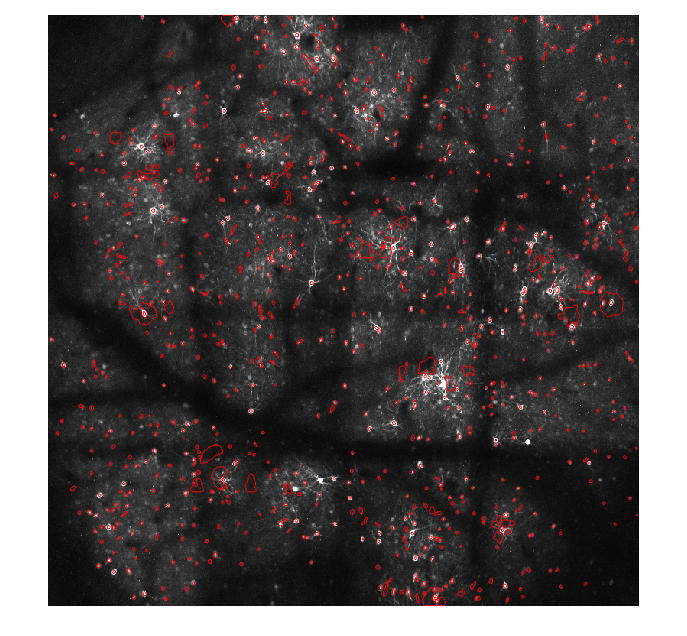

%% Check quality
figure, imshow(max(M,[],3),[0 50]);
plot_cells_overlay(output.spatial_weights,[1,0,0],[])

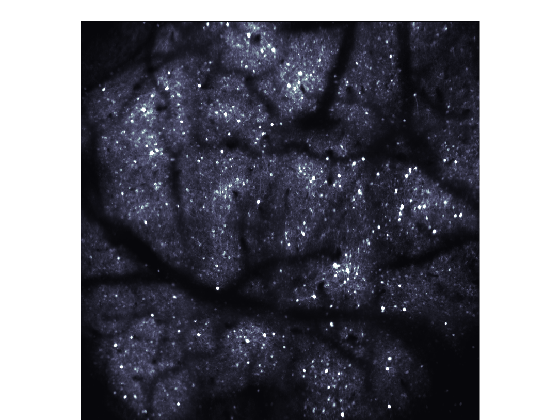

Unrecognized function or variable 'contour_thresh'.
Error in view_movie (line 72)
    plot_cells_overlay(ims,colors,[],contour_thresh);

view_movie(M, 'ims',output.spatial_weights,'im_colors',[1, 0.5, 0])

% Check movie